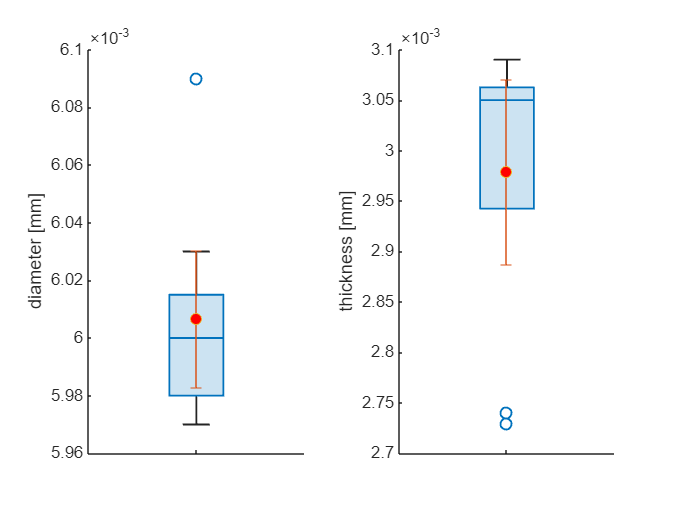

magnet.diameter = 1e-3*[6.00, 6.01, 6.01, 5.99, 5.98, 6.09, 5.97, 5.98, 6.03]';
magnet.thickness = 1e-3*[3.01, 3.01, 3.05, 3.07, 3.05, 3.09, 2.74, 2.73, 3.06]';
magnet.mean_diameter = mean(magnet.diameter);
magnet.std_diameter = std(magnet.diameter);
magnet.sem_diameter = magnet.std_diameter/sqrt(length(magnet.diameter));
magnet.mean_thickness = mean(magnet.thickness);
magnet.std_thickness = std(magnet.thickness);
magnet.sem_thickness = magnet.std_thickness/sqrt(length(magnet.thickness));

figure("Units", "inches", "Position", [0 0 5 3]);
figure_opts = {"Marker", "o", "MarkerFaceColor", "red"};
tlo = tiledlayout('flow');
nexttile;
hold on
boxchart(magnet.diameter);
errorbar(magnet.mean_diameter, 1.96*magnet.sem_diameter)
plot(1, magnet.mean_diameter, figure_opts{:})
hold off
xticklabels([]);
ylabel("diameter [mm]");
nexttile;
hold on
boxchart(magnet.thickness);
errorbar(magnet.mean_thickness, 1.96*magnet.sem_thickness)
plot(1, magnet.mean_thickness, figure_opts{:})
hold off
xticklabels([]);
ylabel("thickness [mm]");

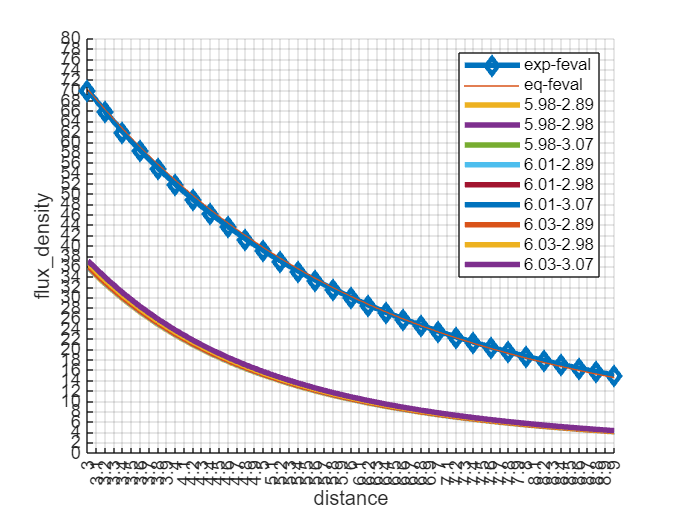

distance = [3; 6; 9; 15]; % [mm];
flux_density = [70; 30; 15; 5]; % [mT] = [Wb/m^2 e-3]
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Normalize = 'on';
[fitresult, gof] = fit( distance, flux_density, 'exp2', opts );



% Create a figure for the plots.
figure( 'Name', 'flux-density-vs-distance');
fontsize(20, "points")
x = 3:0.2:21;
thickness = 6e-3;
distance = x*1e-3;
diameter = 10e-3;
y = estimate_curve(distance, diameter, thickness);
hold on
h = plot( x, feval(fitresult, x), "-d", "LineWidth", 3, "DisplayName", "exp-feval");
plot(x,y, "DisplayName", "eq-feval");
for diameter = [magnet.mean_diameter-1.96*magnet.sem_diameter, magnet.mean_diameter, magnet.mean_diameter + 1.96*magnet.sem_diameter]
    for thickness = [magnet.mean_thickness-1.96*magnet.sem_thickness, magnet.mean_thickness, magnet.mean_thickness+1.96*magnet.sem_thickness]
        y = estimate_curve(distance, diameter, thickness);
        plot(x,y, "LineWidth", 3, 'DisplayName', sprintf("%0.2f-%0.2f", diameter*1e3, thickness*1e3));
    end
end
hold off
legend()
% Label axes
xlabel( 'distance', 'Interpreter', 'none' );
ylabel( 'flux_density', 'Interpreter', 'none' );
grid on
xlim([3,9])
ylim([0, 80])
xticks(1:0.1:21)
yticks(0:2:85)

function y = estimate_curve(distance, diameter, thickness)
b1 = (distance + thickness) ./ sqrt((0.5*diameter)^2 + (distance + thickness).^2);
b2 = distance./sqrt((0.5*diameter)^2 + distance.^2);
y = 3.9e2/2*(b1 - b2);
end